## Parámetros

rotacion = 0;
factor = 4/3;
lmin = 15;
es = 3.5;
hojas = 4;
n = 1000;

lcx = 20;
lcy = 9;

q10 = 170*(pi/180);
q20 = -160*(pi/180);

l1 = 19;
l2 = 18;

## Trébol estilizado

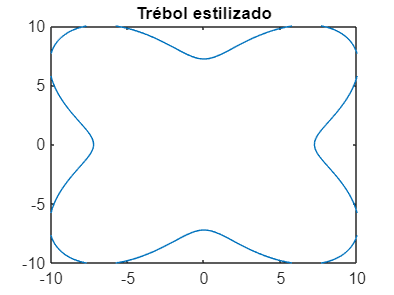

[r,theta]=trayectoria0(rotacion,lmin, factor,es,hojas,n);

xp = r.*cos(theta);
yp = r.*sin(theta);
plot(xp,yp)
title('Trébol estilizado')
a = ((lmin/2)*factor)*(1+sin(rotacion));
xlim ([-a a])
ylim ([-a a])

## Trasladando al origen

[x,y]=Totrigen(lcx,lcy,theta,r);
%plot(x,y)

## Cinemática inversa

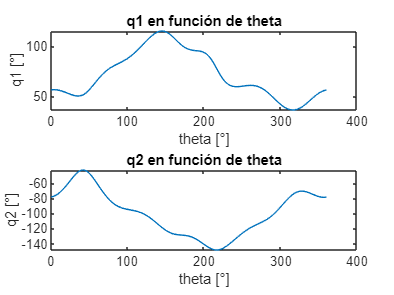

q1 = zeros(length(x),1);
q2 = zeros(length(x),1);
for i = 1:length(x)
    [q1(i), q2(i)] = Cinversa(l1,l2,x(i),y(i),q10,q20);
    q10 = q1(i);
    q20 = q2(i);
end

figure()
subplot(2,1,1);
plot((theta)*(180/pi),q1*(180/pi))
title('q1 en función de theta')
ylabel('q1 [°]')
xlabel('theta [°]')

subplot(2,1,2); 
plot(theta*(180/pi),q2*(180/pi))
title('q2 en función de theta')
ylabel('q2 [°]')
xlabel('theta [°]')